# **RRA**

# **Lab5 (Parteneriat cu laburile scrise de PETrascu)**

## **Recap CO**

**Din pacate, vom nota solutia ecuatiei Riccati cu **$X$, nu $P$

Fie problema de optimizare: $\left\lbrace \begin{array}{l}
\min_{u\left(t\right)\;\mathrm{stabil}} \int_0^{\infty } \left\lbrack x^T \mathrm{Qx}+u^T \mathrm{Ru}+x^T \mathrm{Lu}+u^T L^T x\right\rbrack \mathrm{dt}\\
\mathrm{supus}\;\mathrm{la}:\dot{x} =\mathrm{Ax}+\mathrm{Bu}
\end{array}\right.$. Sa notam $x^T \mathrm{Qx}+u^T \mathrm{Ru}+x^T \mathrm{Lu}+u^T L^T x=I\left(x\left(t\right),u\left(t\right),t\right)$. Sa scriem pe $I$ ca produs de matrici: $I\left(x\left(t\right),u\left(t\right),t\right)=\left\lbrack \begin{array}{cc}
x^T  & u^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
Q & L\\
L^T  & R
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
u
\end{array}\right\rbrack$. Sa notam matricea $\left\lbrack \begin{array}{cc}
Q & L\\
L^T  & R
\end{array}\right\rbrack =P=P^T$. $P$ este matrice simetrica. De ce? $Q$ este $\left\lbrace \begin{array}{l}
\textrm{simetrica}\;\left(Q=Q^T \right)\\
\textrm{pozitiv}\;\textrm{semi}-\textrm{definita}
\end{array}\right.$, iar $R$ este $\left\lbrace \begin{array}{l}
\textrm{simetrica}\;\left(R=R^T \right)\\
\textrm{pozitiv}\;\textrm{definita}
\end{array}\right.$. De asemenea, simetrica lui $L\;\textrm{este}\;L^T$

Aceasta problema este dificil de rezolvat, asa ca sintetizam coeficientii prin aceasta definitie:

#### Triplet Popov

Un triplet de matrice $\Sigma :=\left(A;B;P\right)=\left(A;B;Q,L,R\right),\left\lbrack \begin{array}{cc}
Q & L\\
L^T  & R
\end{array}\right\rbrack =P=P^T$, unde $\left\lbrace \begin{array}{l}
A\in {\mathbb{R}}^{\textrm{nxn}} \\
B\in {\mathbb{R}}^{\textrm{nxm}} \\
Q=Q^T \in {\mathbb{R}}^{\textrm{nxn}} \\
L\in {\mathbb{R}}^{\textrm{nxm}} \\
R=R^T \in {\mathbb{R}}^{\textrm{mxm}} 
\end{array}\right.\Rightarrow P\in {\mathbb{R}}^{\left(n+m\right)x\left(n+m\right)}$ se numeste **Triplet Popov**

Fie 2 triplete Popov: $\left\lbrace \begin{array}{l}
\Sigma :=\left(A;B;\left\lbrack \begin{array}{cc}
Q & L\\
L^T  & R
\end{array}\right\rbrack \right)\\
\tilde{\Sigma} :=\left(\tilde{A} ,\tilde{B} ,\left\lbrack \begin{array}{cc}
\tilde{Q}  & \tilde{L} \\
\tilde{L^T }  & \tilde{R} 
\end{array}\right\rbrack \right)
\end{array}\right.$. Ele se numesc $\left(X,F\right)$-echivalente daca $\exists \left\lbrace \begin{array}{l}
F\in {\mathbb{R}}^{\textrm{mxm}} \\
X=X^T \in {\mathbb{R}}^{\textrm{nxn}} 
\end{array}\right.$ astfel incat$\left\lbrace \begin{array}{l}
\tilde{A} =A+\textrm{BF}\\
\tilde{B} =B\\
\tilde{Q} =Q+\textrm{LF}+L^T F^T +F^T \textrm{RF}+\tilde{A^T } X+X\tilde{A} \\
\tilde{F} =L+F^T R+\textrm{XB}\\
\tilde{R} =R
\end{array}\right.$. $\tilde{Q}$ este simetrica

- **Feedback echivalent (F-echivalent) are loc cand **$X=0$. Practic, scap de $\tilde{A^T } X+X\tilde{A}$ si de $\textrm{XB}$.

- **Echivalent redus**: $F=0$ si $\tilde{Q} =0$. Practic $X$ sa respecte **Ecuatia Lyapunov**$\tilde{A^T } X+X\tilde{A} +Q=0$

Folosind un triplet Popov asociem diferite concepte (obiecte) algebrice care joaca un rol central in caracterizarea solutiilor problemei de regalre asociate. Mai mult, vedem cum aceste obiecte se transforma sub relatia de echivalenta

- Indice patratic (si solutia ascociata)

- Sistem Hamiltonian **(SH)** (asociat PLP)

- Operator Intrare-Iesire al SH

- MT a **SH**: Functia Popov

- Fascicul de Zerouri (Sistem) al **SH**: Fascicul Hamiltonian **(FH)**

- Ecuatia Matriceala Algebrica Riccati **(EMAR)**

- Sistemul Kalman-Yakubovixh-Popov **(SKYP)**

## Indicele patratic

$\min_{u\in {\mathcal{U}}_{\zeta } } J_{\Sigma } \left(u\left(t\right),\zeta \right),\textrm{cu}\;\zeta$conditile initiale

supus la $\dot{x} =\textrm{Ax}+\textrm{Bu}$, $t\ge t_0 ,x\left(t_0 \right)=x_0 =\zeta$. Asta este o problema Cauchy, $x\left(0\right)=\zeta ,u\in {\mathcal{U}}_{\zeta } =\left\lbrace u\in {\mathcal{L}}_+^{2,m} :x\in {\mathcal{L}}_+^{2,n} \right\rbrace$, unde ${\mathcal{L}}_+^{2,m,n}$ sunt semnale cu m,n componente de energie finita si cu suport semi-pozitiv $\left(u\left(t\right)=0,\forall t<0\right)$

${\mathcal{U}}_{\zeta }$ contin intarile care fac ca solutia $x^{\zeta ,u} \left(t\right)=e^{\textrm{At}} *\zeta +\int_0^t e^{A\left(t-\tau \right)} \textrm{Bu}\left(\tau \right)d\tau ,t\ge 0$, unde $\left\lbrace \begin{array}{l}
e^{\textrm{At}} \zeta =\textrm{raspuns}\;\textrm{liber}\;\left(\phi \zeta \right)\\
\int_0^t e^{A\left(t-\tau \right)} \textrm{Bu}\left(\tau \right)d\tau =\textrm{raspuns}\;\textrm{fortat}\;\left(\mathcal{L}u\right)
\end{array}\right.$ sa aiba norma de patrat integrabil. Aceste intrari, care sunt solutia $\dot{x} =\textrm{Ax}+\textrm{Bu}$, stabilizeaza sistemul

**Daca doamne ajuta A este stabil**, $J_{\Sigma } \left(\zeta ,u\right)$ este definit $\forall \;\zeta \in {\mathbb{R}}^n$ si $u\in {\mathcal{L}}_+^{2,m}$i.e ${\mathcal{U}}_{\zeta } ={\mathcal{L}}_+^{2,m}$. Rescriu aici ca $u\in {\mathcal{U}}_{\zeta }$

**Cine este acel **$J_{\Sigma } \left(\zeta ,u\right)$**? Haide sa il scriem: **$J_{\Sigma } \left(\zeta ,u\right)=\int_0^{\infty } \left\lbrack \begin{array}{cc}
x & u
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
Q & L\\
L^T  & R
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
u
\end{array}\right\rbrack \textrm{dt}$. Sa ne uitam mai exact la forma lui, mai ok: $J_{\Sigma } \left(\zeta ,u\right)=\int_0^{\infty } \left\lbrack x^T \textrm{Qx}+u^T \textrm{Ru}+x^T \textrm{Lu}+u^T L^T x\right\rbrack \textrm{dt}$. Practic este Ecuatia Riccati pe care o stim noi de la CO, dar scrisa ca produs de matrici.

**Pana sa trecem mai departe, vreau sa reamintesc ceva:**

Produsul intern dintre $x,y\in {\mathbb{R}}^n$,$<x,y>\;=x^T y$. Ca reminder, un produs intern poate induce o norma. $<x,x>=x^T x=||x||_f^2$.

Ok, cum pot translata asta la ce avem. Hai sa vedem:

Fie $f,g\in {\mathcal{L}}_+^{2,m}$. Definim produsul intern asa: $<f,g>\;=\int_0^{\infty } f^T \left(t\right)g\left(t\right)\textrm{dt}$. De asemenea, pot sa am norma si aici: $<f,f>\;=\int_0^{\infty } f^T \textrm{fdt}=\int_0^{\infty } ||f||_F^2$

Sa scriem Ecuatia Riccati $J_{\Sigma } \left(\zeta ,u\right)$ in forma de produs intern: $J_{\Sigma } \left(\zeta ,u\right)=<\left\lbrack \begin{array}{c}
x\\
u
\end{array}\right\rbrack ,P\left\lbrack \begin{array}{c}
x\\
u
\end{array}\right\rbrack >,\textrm{unde}\;$$u\in {\mathcal{U}}_{\zeta }$. De aici rezulta ca ${\textrm{xe}}^{\zeta ,u} ={\mathcal{L}}_+^{2,m}$. Ce inseamna asta? $J_{\Sigma } \left(\zeta ,u\right)$ este o cantitate finita

Noi ce stim pana acum? Dorim $\left\lbrace \begin{array}{l}
\min_{u\in {\mathcal{U}}_{\zeta } } J_{\Sigma } \left(u\left(t\right),\zeta \right)\\
s\ldotp l\ldotp \dot{x} =\textrm{Ax}+\textrm{Bu}
\end{array}\right.$. Putem folosi aici **principiul Pontryagin.** El spune asa: o conditie necesara pentru a rezolva problema de control optimal, este ca acesta sa fie ales, astfel incat sa se optimizeze **Hamiltonianul**.

Fie $\min \int_0^{\infty } \left(x\left(t\right),u\left(t\right),t\right)\textrm{dt}$. Definim o matrice Hamilton $H\left(x,u,\tilde{\lambda} ,t\right)=-I+{\tilde{\lambda} }^T \left(t\right)\left(\textrm{Ax}\left(t\right)+\textrm{Bu}\left(t\right)\right)$. Am pus acel - la $I$ pentru ca vreau minim si nu maxim. De obicei, Pontryagin eset folosit pentu a vedea maximul $\left(\max \;J=-\min -J\right)$

**Pentru optimalitate, trebuie:**$\left\lbrace \begin{array}{l}
\nabla_u H=0\\
\nabla_{\tilde{\lambda} } H=\dot{x} \left(t\right)\\
\nabla_{\lambda } H=-\dot{\lambda} 
\end{array}\right.$, unde $\nabla =\textrm{gradientul}$. Pana sa continuam, sa ne reamintim cate ceva: $\left\lbrace \begin{array}{l}
\nabla_x \left(x^T \textrm{Qx}\right)=2\textrm{Qx}\\
\nabla_x \left(y^T \textrm{Qx}\right)=\nabla_x \left(x^T Q^T y\right)=Q^T y
\end{array}\right.$. Ok, sa continuam: Sa scriem Hamiltonianul: $H=-I+{\tilde{\lambda} }^T \left(t\right)\left(\textrm{Ax}\left(t\right)+\textrm{Bu}\left(t\right)\right)$=${-x}^T \textrm{Qx}-u^T \textrm{Ru}-x^T \textrm{Lu}-u^T L^T x+{\tilde{\lambda} }^T \textrm{Ax}+{\tilde{\lambda} }^T \textrm{Bu}$. Acum sa facem gradienti pentru $u,\tilde{\lambda} \;\textrm{si}\;\lambda$:$\left\lbrace \begin{array}{l}
\nabla_u H=-2\textrm{Ru}-2L^T x+B^T \tilde{\lambda} =0=V\\
\nabla_{\tilde{\lambda} } H=\textrm{Ax}+\textrm{Bu}=0\\
\nabla_{\lambda } H=-2\textrm{Qx}-2\textrm{Lu}+A^T \tilde{\lambda} =-\dot{\tilde{\lambda} } 
\end{array}\right.$. Inmultim prima egalitate cu $-\frac{1}{2}$, iar a treia cu $\frac{1}{2}$. Asadar, avem:$\left\lbrace \begin{array}{l}
\nabla_u H=0\\
\nabla_{\tilde{\lambda} } H=\dot{x} \left(t\right)\\
\nabla_{\lambda } H=-\dot{\lambda} 
\end{array}\right.$ si $\left\lbrace \begin{array}{l}
\nabla_u H=-2\textrm{Ru}-2L^T x+B^T \tilde{\lambda} =0=V\\
\nabla_{\tilde{\lambda} } H=\textrm{Ax}+\textrm{Bu}=0\\
\nabla_{\lambda } H=-2\textrm{Qx}-2\textrm{Lu}+A^T \tilde{\lambda} =-\dot{\tilde{\lambda} } 
\end{array}\right.$. De aici scoatem ca $\left\lbrace \begin{array}{l}
\dot{x} =\textrm{Ax}+\textrm{Bu}\\
-\frac{\tilde{\dot{\lambda} } }{2}=-\textrm{Qx}-\textrm{Lu}+\frac{A^T \tilde{\lambda} }{2}\\
0\equiv V=L^T x+\textrm{Ru}+B^T \frac{\tilde{\lambda} }{2}
\end{array}\right.$. Sa facem notatia$\frac{\tilde{\lambda} }{2}=\lambda$. Acum o sa obtinem

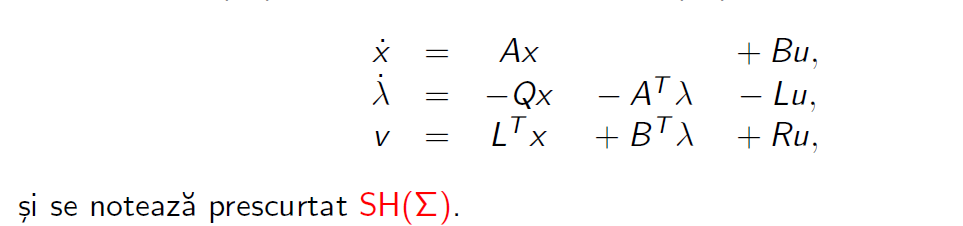

Ce interes avem? Intrarea sa fie punct stationar pentru functie. In acest caz, iesirea sa fie 0. Mai specific, $V=0$.

**O chestie importanta:** trebuie sa stim pe ce multime lucram, adica cat este ${\mathcal{U}}_{\zeta } =?$ Daca $\Lambda \left(A\right)\in {\mathbb{C}}_- \Rightarrow {\mathcal{U}}_{\zeta } ={\mathcal{L}}_+^{2,n}$

Fie 2 triplete Popov $\left\lbrace \begin{array}{l}
\Sigma :=\left(A;B;\left\lbrack \begin{array}{cc}
Q & L\\
L^T  & R
\end{array}\right\rbrack \right)\\
\tilde{\Sigma} :=\left(\tilde{A} ,\tilde{B} ,\left\lbrack \begin{array}{cc}
\tilde{Q}  & \tilde{L} \\
\tilde{L^T }  & \tilde{R} 
\end{array}\right\rbrack \right)
\end{array}\right.$ $\left(X,F\right)$ echivalente.  Atunci $J_{\Sigma } \left(\zeta ,u\right)=J_{\tilde{\Sigma} } \left(\zeta ,\tilde{u} \right)+\zeta^T X\zeta$, unde $\tilde{\;u} =u-{\textrm{Fx}}^{\zeta ,u}$. Daca u este luat optim, atunci $J_{\Sigma } \left(\zeta ,u_{\textrm{optim}} \right)=\zeta^T X\zeta \Rightarrow u_{\textrm{optim}} ={\textrm{Fx}}^{\zeta ,u} \;\textrm{si}\;\textrm{"dispare"}J_{\tilde{\Sigma} } \left(\zeta ,\tilde{u} \right)\;$ , ceea ce explica cum merge LQR-ul

**Ok ok, dar ce se intampla cu iesirea sistemului Hamiltonian prin **$\left(X,F\right)$ echivalenta? Fie acelasi triplet Popov. Trebuie sa cautam $\left(x^* ,u^* ,\lambda^* \right)\;\textrm{astfel}\;\textrm{incat}\;V\left(t\right)=0,\forall t\in \mathcal{T}\;\textrm{pentru}\;\textrm{SH}\left(\Sigma \right)\Leftrightarrow$$\left(x^* ,u^* -{\textrm{Fx}}^* ,\lambda^* -{\textrm{Xx}}^* \right)\Rightarrow V\left(t\right)=0,\;\forall t\in \mathcal{T}\;\textrm{pentru}\;\textrm{SH}\left(\tilde{\Sigma} \right)$. In acest sens, cum am observat si mai devreme pe $\textrm{SH}\left(\tilde{\Sigma} \right)$, $\left\lbrace \begin{array}{l}
u^* ={\textrm{Fx}}^* \\
\lambda^* ={\textrm{Xx}}^* 
\end{array}\right.$

#### Important:

Exista mereu triplet Popov pentru care iti dau solutiile de mai sus.

#### Cate ceva de stiut:

- Pentru $\left(X,F\right)$ alese bine, o sa avem cazuri simple

- Nu neaparat singura metoda, dar este utila pentru "recupararea" formulelor si de unde vin pasii de la Control Optimal de cum se introduce Ecuatia Riccati Si se arata ca $J_{\Sigma } \left(\zeta ,u\right)=\zeta^T X\zeta$

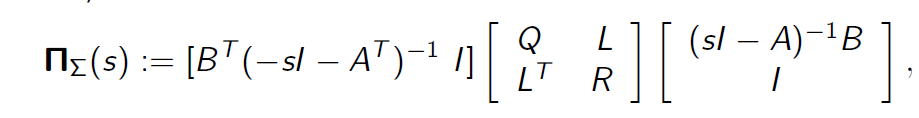 se numeste **Functie Popov **$\left(\prod_{\Sigma } \right)$. $\prod_{\Sigma } =\left\lbrack \begin{array}{ccc}
A & 0 & B\\
-Q & -A^T  & -L\\
L^T  & B^T  & R
\end{array}\right\rbrack$este Matricea de Transfer de la intrarea u la iesirea v a Sistemului Hamiltonian $\textrm{SH}\left(\Sigma \right)$

**Sa reluam putin:**

Fie sistemul Hamiltonial

Vrem $\left(x^* ,u^* ,\lambda^* \right)\;\textrm{astfel}\;\textrm{incat}\;V\left(t\right)=0,\forall t\in \mathcal{T}$, iar $u\in {\mathcal{U}}_{\zeta } =\left\lbrace u\in {\mathcal{L}}_+^{2,n} \;|\;x^{\zeta ,u} \in {\mathcal{L}}_+^{2,n} \right\rbrace$

Asadar, ne uitam la 0-uri, pentru ca noi fortam iesirea la 0

Pana sa ne uitam la **0-urile de invarianta**, sa scriem Sistemul Hamiltonian in forma matriceala: $\textrm{SH}\left(\Sigma \right)=\left\lbrack \begin{array}{ccc}
A & 0 & B\\
-Q & -A^T  & -L\\
L^T  & B^T  & R
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A_{\Sigma }  & B_{\Sigma } \\
C_{\Sigma }  & D_{\Sigma } 
\end{array}\right\rbrack$

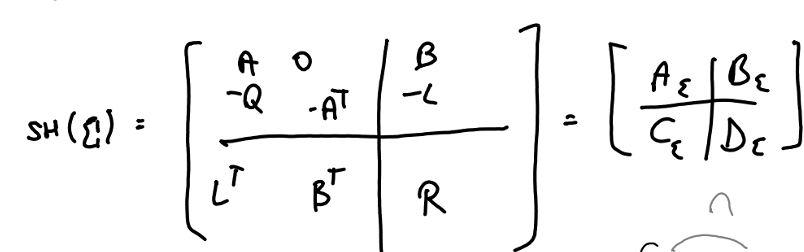

Fascicolul de 0-uri al $\textrm{SH}\left(\Sigma \right)$ se numeste **Fascicul Hamiltonian (Extins) **$\textrm{FH}\left(\Sigma \right)$. Cum arata acesta?

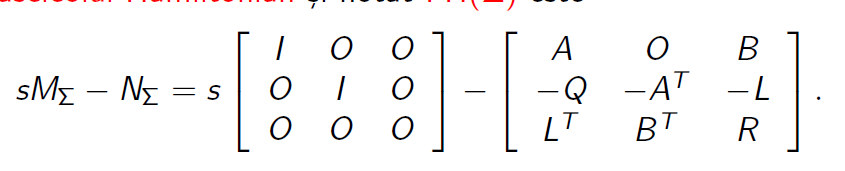

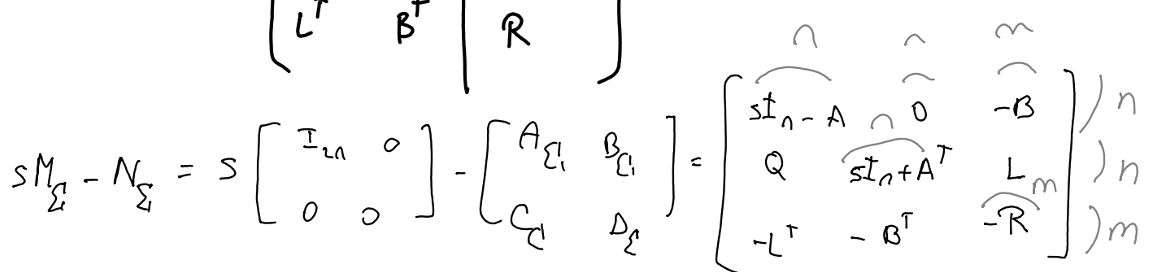

Acest fascicul este patrat. In plus, daca $\det \left({\textrm{sM}}_{\Sigma } -N_{\Sigma } \right)\not= 0$, atunci acest Fascicul Hamiltonian se mai numeste si regulat

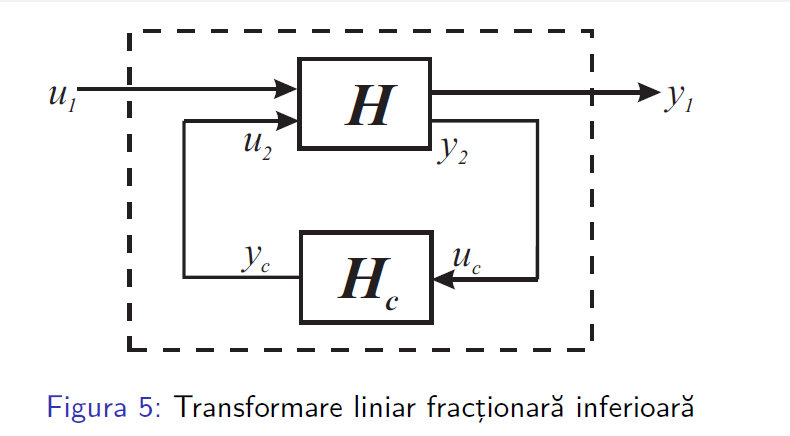

Fie acest $\textrm{TLFi}\left(T,K\right)$. De obicei, K minimizeaza pe ${u_1 \to y}_1$, mai precis $||T_{11} ||_{\infty }$

Deci putem avea $\left\lbrace \begin{array}{l}
\min_{u_2 } \max_{u_1 } ||y_1 ||\\
\max_{u_1 } \min_{u_2 } ||y_1 ||
\end{array}\right.$, noi implicit stim $u_1$. Aici sunt echivalente, in optimizari nu prea. *De obicei se prefera a doua varianta*

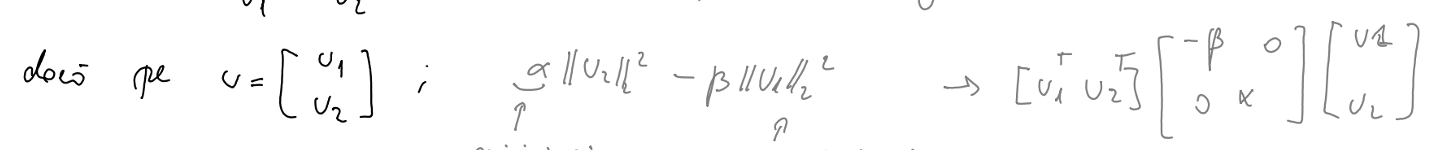

Aici nu stim signatura lui R

**In ceea ce facem, vom presupune ca R este inversabil, pentru ca Sistemul Algebric Riccati sa NU fie in contradictie cu Popov**

In acest send, transformarea de echivalenta de $\left\lbrace \begin{array}{l}
Q=\left\lbrack \begin{array}{ccc}
I & 0 & -{\textrm{BR}}^{-1} \\
0 & I & {\textrm{LR}}^{-1} \\
0 & 0 & I
\end{array}\right\rbrack \\
Z=\left\lbrack \begin{array}{ccc}
I & 0 & 0\\
0 & I & 0\\
-R^{-1} L^T  & -R^{-1} B^T  & R^{-1} 
\end{array}\right\rbrack 
\end{array}\right.$ matrici inversabile arata asa:


$$Q\left({\textrm{sM}}_{\Sigma } -N_{\Sigma } \right)Z=s\tilde{M_{\Sigma } } -\tilde{N_{\Sigma } } =s\left\lbrack \begin{array}{cc}
I_{2n}  & 0\\
0 & 0
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
H_{\Sigma }  & 0\\
0 & I_m 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
{\textrm{sI}}_{2n} -H_{\Sigma }  & 0\\
0 & -I_m 
\end{array}\right\rbrack$$


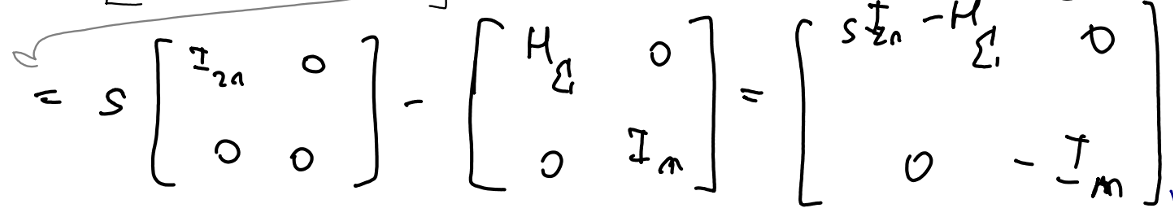

**Asta este o forma canonica Weierstrass**

Sa aflam determinantul: $\det \left(s\tilde{M_{\Sigma } } -\tilde{N_{\Sigma } } \right)={\left(-1\right)}^m \det \left({\textrm{sI}}_{2n} -H_{\Sigma } \right)$, **care trebuie sa fie DIFERIT DE 1. Normal asta este garantat**

Asadar, daca $\exists R^{-1} \Rightarrow$ Fascicolul Hamiltonian (FH) este regulat

**Informatie de revazut, sper ca-i corect: **Fascilului Hamiltonian are m Valori Proprii Generalizatea (V.P.G) infinite SIMPLE daca nu are o realizare minimala

#### Matrice Hamilton $H_{\Sigma }$

Mai intai sa luam matricea antisimetric $J=\left\lbrack \begin{array}{cc}
0_n  & I_n \\
-I_n  & 0_n 
\end{array}\right\rbrack$. O matrice Hamilton $H_{\Sigma } \in {\mathbb{R}}^{2\textrm{nx2n}}$ respecta urmatoarea egalitate: ${\left(JH_{\Sigma } \right)}^T =JH_{\Sigma }$. In acest sens, are simetrie a spectrului in raport cu axa imaginara, adica daca avem $\lambda ,\textrm{avem}\;\textrm{si}\;\bar{\lambda} ,-\lambda \;\textrm{si}-\bar{\lambda}$

**Cum arata ea:**


$$H_{\Sigma } =\left\lbrack \begin{array}{cc}
A-{\textrm{BR}}^{-1} L^T  & -{\textrm{BR}}^{-1} B^T \\
-Q+{\textrm{LR}}^{-1} L^T  & -{\left(A-{\textrm{BR}}^{-1} L^T \right)}^T 
\end{array}\right\rbrack$$
   
$$H_f =\left\lbrack \begin{array}{cc}
A_f  & -B_f R_n^{-1} B_f^T \\
-Q_n  & -A_f^T 
\end{array}\right\rbrack$$


**Am atasat si Matricea Hamilton post-avarie de la CO, pentru a vedea ca aceste 2 matrici au aceeasi forma. La CO consideram acel L ca fiind 0**

Noi vrem asa:

- Sa ducem iesirea $V\equiv 0\Rightarrow$ ne uitam la 0-uri

- Sa stabilizam sistemul original. Asta inseamna ca 0-uril sa fie stabile

- Pentru ca este o matrice Hamilton, vrem n zerouri in ${\mathbb{C}}_-$

#### Pentru R inversabil, problemele noastre se rezolva pentru ca putem scrie:

**EMAR (Ecuatia Matriceala Algebrica Riccati)**

EMAR$\left(\Sigma \right)=A^T X+\textrm{XA}+Q-\left(\textrm{XB}+L\right)R^{-1} \left(B^T X+L^T \right)$


$$A_f^T P_f +P_f A_f -{P_f B_f R}_n^{-1} B_f^T P_f +Q_n$$


**Am atasat si Riccati post-avarie de la CO, pentru a se observa ca este aceeasi forma, doar avem acel L in plus**

Pentru $\textrm{EMAR}\left(\Sigma \right)=0$, $X_s$ este **solutia stabilizatoare**. Daca exista, aceasta este unica. Putem scrie $F={-R}^{-1} \left(B^T X+L^T \right)$    $K_f =R_n^{-1} B_f^T P_f$. Acest F poarte nume de R**eactia Stabilizatoare Riccati.**

**La fel, am atasat Solutia stabilizatoare din Riccati post-avarie. Se poate vedea ca este iar aceeasi forma**

Fie 2 triplete Popov $\left\lbrace \begin{array}{l}
\Sigma :=\left(A;B;\left\lbrack \begin{array}{cc}
Q & L\\
L^T  & R
\end{array}\right\rbrack \right)\\
\tilde{\Sigma} :=\left(\tilde{A} ,\tilde{B} ,\left\lbrack \begin{array}{cc}
\tilde{Q}  & \tilde{L} \\
\tilde{L^T }  & \tilde{R} 
\end{array}\right\rbrack \right)
\end{array}\right.$ $\left(X,F\right)$ echivalente. $X_s$ este **solutia stabilizatoare a **$\textrm{EMAR}\left(\Sigma \right)\Leftrightarrow$$X_s -X$ este solutia $\textrm{EMAR}\left(\tilde{\Sigma} \right)$. Mai mult, $\tilde{F_{\textrm{Ricc}} } =F_{\textrm{Ricc}} -F$, unde $F_{\textrm{Ricc}}$ este R**eactia Stabilizatoare Riccati.**

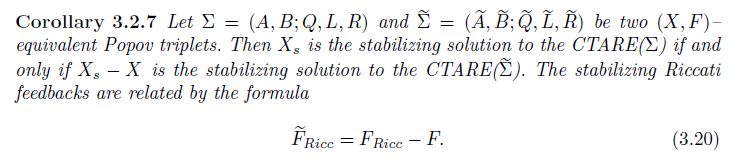

### O alta elternativa pentru a rezolva probleme de CO:

#### Sistem Kalman-Yakubovich-Popov (SKYP)

Fie tripletul Popov $\Sigma :=\left(A;B;\left\lbrack \begin{array}{cc}
Q & L\\
L^T  & R
\end{array}\right\rbrack \right)$, cu R inversabil si J matricea de semn a formei canonice Jordan pentru R, de dimensiune mxm. **Sistemul**

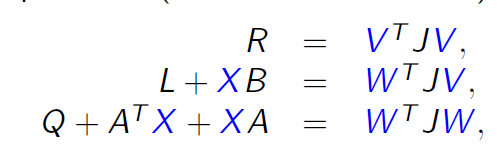

se numeste **Sistem Kalman-Yakubovich-Popov (SKYP).** Cum **R este inversabil si simetric**, adica are spectrul real cu $m_1$ valori stabile proprii si $m_2$ valori instabile proprii, avem ca $J=\left\lbrack \begin{array}{cc}
-I_{m_1 }  & 0\\
0 & I_{m_2 } 
\end{array}\right\rbrack$. **Din cate se poate vedea, matricea de signatura **$J$** este inversabila si simetrica**. $m_1 +m_2$ este dimnesiunea matricii R

Fun fact: daca facem $W=0\;\mathrm{si}\;V=0$ si mai ordonam astea, obtinem EMAR

#### Pana sa trecem mai departe, sa clarificam restul de termeni:

$V$ se ia ca factor Cholesky

Fie Solutia $\textrm{SKYP}\left(\Sigma \right)=\left(X,V,W\right)$. Daca $\Lambda \left(A+\textrm{BF}\right)\in {\mathbb{C}}_-$, unde $F=-V^{-1} W$, atunci $F$** este solutia stabilizatoare** $\textrm{SKYP}\left(\Sigma \right)$

De ce folosim uratenia asta, daca avem deja Riccati ala care arata scarbos? Este mai simplu sa vedem in cele 3 egalitati decat sa ne uitam in Riccati

Cateva avantaje:

- **Mostenire infromatii despre signatura**: Avand forma asta SKYP si acea matrice J de sigantura, permite sistemului sa "mosteneasca" signatura fuctiei Popov asociata, ceea ce la Riccati nu se poate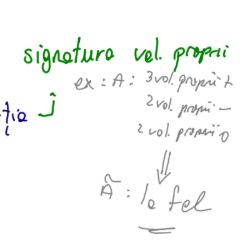

- **Formulare mai simpla si compacta:** Prin SKYP se poate scrie in mod mai simplu Ecuatia lui Riccati. Pentru probleme complexe, atat modul de rezolvare, cat si solutia acesteia pot fi exprimate in o forma mai compacta si mai simpla fata de a folosi Riccati.

## Laborator

clear
close all
clc

Luam A si B

A = randi(9,3,3)

A =      2     6     3
     6     5     7
     7     5     2



B = randi(9,3,4)

B =      7     6     9     4
     2     8     7     5
     4     1     5     3


IMPORTANT: Vedem daca sistemul este controlabil

Pc = ctrb(A,B);

Prin matricea de ctrb

disp(rank(Pc))

     3



Prin zerouri de inivarianta

tzero(A,B,[],[])


ans =

  0×1 empty double column vector



Acum definesc Q

Q = randn(3)

Q =     0.0230    1.5270    0.6252
    0.0513    0.4669    0.1832
    0.8261   -0.2097   -1.0298


Il fac simetric

Q = Q*Q'

Q =     2.7231    0.8287   -0.9450
    0.8287    0.2542   -0.2442
   -0.9450   -0.2442    1.7868


Il definesc pe R

R = randn(4)

R =     0.9492    0.2614   -0.5320   -0.7120
    0.3071   -0.9415    1.6821   -1.1742
    0.1352   -0.1623   -0.8757   -0.1922
    0.5152   -0.1461   -0.4838   -0.2741


Acum il fac simetric

R = R*diag([1 2 -3 -4])*R'

R =    -1.8392   -0.8602   -1.9018   -1.1400
   -0.8602  -12.1364    3.8635    1.5874
   -1.9018    3.8635   -2.3776   -1.3648
   -1.1400    1.5874   -1.3648   -0.6945



eig(R)

ans =   -13.7719
   -4.0693
    0.0784
    0.7150


Asta este acel L in plus de la Riccati

L = 1e-3 * randn(3,4)

L =     0.0015    0.0016   -0.0015    0.0003
   -0.0002    0.0012   -0.0004   -0.0003
   -0.0011   -0.0002   -0.0002    0.0004


Pacanea, uneori imi da ca nu are solutie

[X,F] = icare(A,B,Q,R,L)

X =    -1.0509   -1.0492   -1.4416
   -1.0492   -0.9446   -1.2615
   -1.4416   -1.2615   -1.1280


F =    18.6701   17.1320   21.4588
   -2.4272   -2.2311   -2.8826
   -4.7900   -5.0466   -7.1905
   -6.9484   -5.0115   -5.4262


Am facut conventie ca scriem $F=-F$, de-aia avem acel + la bucla inchisa

F = -F

F =   -18.6701  -17.1320  -21.4588
    2.4272    2.2311    2.8826
    4.7900    5.0466    7.1905
    6.9484    5.0115    5.4262



eig(A + B*F)

ans =  -11.7619 + 0.0000i
  -5.6070 + 0.4088i
  -5.6070 - 0.4088i


Facem forma Schur la R si scoatem U si T, apoi le ordonam ca prima jumate sa aiba partile stabile, iar cealalta partile instabile

[U,T] = schur(R)

U =    -0.0001    0.7293   -0.1225    0.6731
    0.9311    0.2470   -0.0053   -0.2684
   -0.3334    0.5356   -0.4146   -0.6558
   -0.1478    0.3468    0.9017   -0.2117


T =   -13.7719         0         0         0
         0   -4.0693         0         0
         0         0    0.0784         0
         0         0         0    0.7150



[Uord, Tord] = ordschur(U,T,'lhp')

Uord =    -0.0001    0.7293   -0.1225    0.6731
    0.9311    0.2470   -0.0053   -0.2684
   -0.3334    0.5356   -0.4146   -0.6558
   -0.1478    0.3468    0.9017   -0.2117


Tord =   -13.7719         0         0         0
         0   -4.0693         0         0
         0         0    0.0784         0
         0         0         0    0.7150


Cum arata Schur?

Aceasta se scrie $A={\textrm{USU}}^T$, unde $\left\lbrace \begin{array}{l}
U^T U=I\Rightarrow \Lambda \left(S\right)=\Lambda \left(A\right),\;U\;\textrm{matrice}\;\textrm{ortogonala}\\
S\;\textrm{este}\;o\;\textrm{matrice}\;\textrm{superior}\;\textrm{triunghiulara}\;\textrm{care}\;\textrm{are}\;\textrm{pe}\;D\ldotp P\;\;\textrm{valorile}\;\textrm{proprii}
\end{array}\right.$

#### Matrice ortogonala: $U^T =U^{-1}$

Din cate se poate vedea, rescriem T din forma Schur altfel: $|T|^{\frac{1}{2}} *\mathrm{sgn}\left(T\right)*|T|^{\frac{1}{2}}$. T este matrice diagonala, deci se poate scrie asa


$$R=U*|T{\mathrm{ord}|}^{\frac{1}{2}} *\mathrm{sgn}\left(\mathrm{Tord}\right)*|T{\mathrm{ord}|}^{\frac{1}{2}} *U^T$$


To = diag(diag(Tord))

To =   -13.7719         0         0         0
         0   -4.0693         0         0
         0         0    0.0784         0
         0         0         0    0.7150


J este matricea de signatura

J = sign(To)

J =     -1     0     0     0
     0    -1     0     0
     0     0     1     0
     0     0     0     1


Ce se poate observa? Sa punem cele 2 egalitati impreuna: $\left\lbrace \begin{array}{l}
R=U*|T{\mathrm{ord}|}^{\frac{1}{2}} *\mathrm{sgn}\left(\mathrm{Tord}\right)*|T{\mathrm{ord}|}^{\frac{1}{2}} *U^T \\
R=V^T \mathrm{JV}
\end{array}\right.$. $\mathrm{sgn}\left(\mathrm{Tord}\right)=J$, pentru ca J este matrice de signatura, precum este sgn(Tord).

Acum aflu acest V. Cum mai precis? $V=\sqrt{\mathrm{abs}\left(\mathrm{To}\right)}*U_{\mathrm{ord}}^T$. Nu radical de matrice, ci radical de fiecare element din matrice

V = sqrt(abs(To))*Uord'

V =    -0.0005    3.4554   -1.2374   -0.5486
    1.4712    0.4982    1.0804    0.6996
   -0.0343   -0.0015   -0.1161    0.2525
    0.5692   -0.2269   -0.5545   -0.1790



$$R=V^T \mathrm{JV}$$


norm(R - V' * J * V)

ans = 1.1174e-14

Acum calculez W acela: transpun  $\mathrm{XB}+L=W^T \mathrm{JV}$ si scot W

**In MATLAB, a\b face b/a**

W = (V' * J) \ (B' * X + L')

W =     1.3425    1.2757    1.9030
   16.2217   15.1344   18.5688
   -1.8352   -1.2638   -1.2669
   15.0773   13.9529   17.8264


 
$$\mathrm{XB}+L=W^T \mathrm{JV}$$


norm(A' * X + X * A + Q - W' * J * W)

ans = 3.9097e-13

Acum verific egalitatea $F=-V^{-1} W$ si daca am scris corect solutia stabilizatoare

norm(V*F + W)

ans = 1.4482e-13